# Surrogate Optimization

*© *Copyright 2022 The MathWorks, Inc

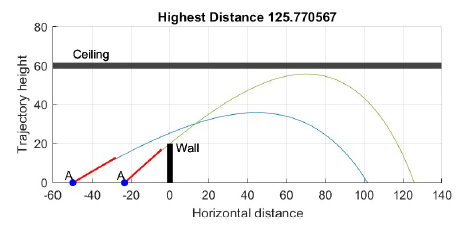

## Parameters

param.wallheight = 20;
param.peak = 60;
param.resistancecoeff = 0.01;
param.initialspeed = 85;
param.lb = [ -200; 0.05];
param.ub = [ -1; pi/2-0.05];
param.gravity = 9.81;
param.x0 = [ -50; pi /6];
param.stoptime = 15

param = struct with fields:
         wallheight: 20
               peak: 60
    resistancecoeff: 0.0100
       initialspeed: 85
                 lb: [2×1 double]
                 ub: [2×1 double]
            gravity: 9.8100
                 x0: [2×1 double]
           stoptime: 15


## Call Model Solver (returning a structure)

sol = ModelSolver(param.x0, param)

sol = struct with fields:
     solver: 'ode45'
    extdata: [1×1 struct]
          x: [0 4.7283e-06 2.8370e-05 1.4658e-04 7.3761e-04 0.0037 0.0185 0.0923 0.4617 1.0124 1.7007 2.6828 4.1293 5.6293 7.1293 8.6293 10.1293 11.6293 13.1293 14.6293 15]
          y: [4×21 double]
      stats: [1×1 struct]
      idata: [1×1 struct]


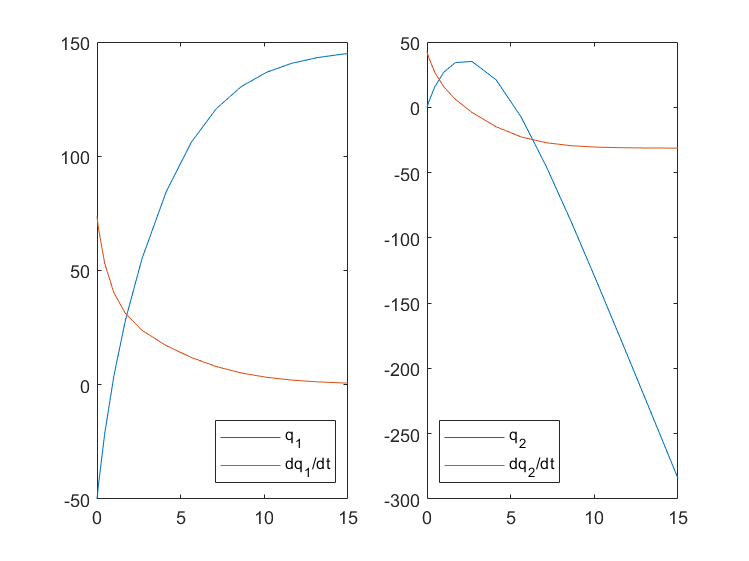


figure, subplot(1,2,1)
plot(sol.x, sol.y([1 3],:)')
legend("q_1", "dq_1/dt", Location="southeast")
subplot(1,2,2)
plot(sol.x, sol.y([2 4],:)')
legend("q_2", "dq_2/dt", Location="southwest")

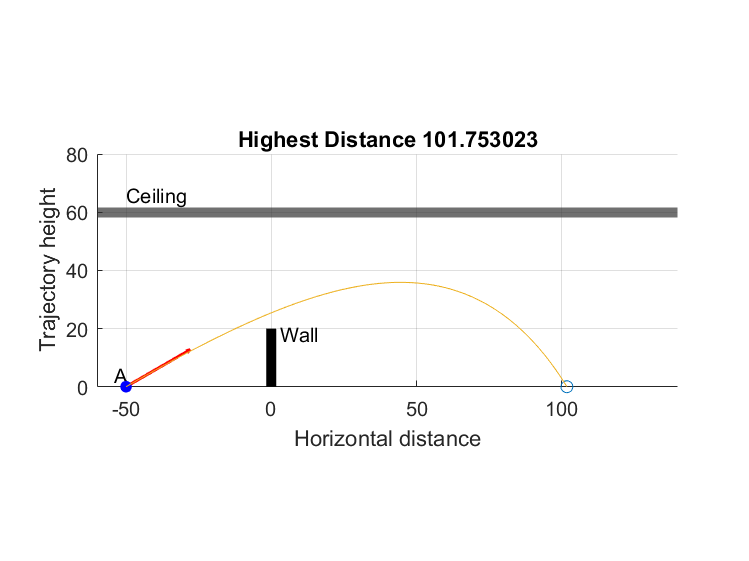

dist = 101.7530

landingtime = 5.2846


f = figure;
[dist,landingtime] = plotSolution(param.x0,param, f,"animation")

## Call ObjectiveConstr (returning a structure)

First change interface by embedding param, so that we get a function handle depending only upon x:

obj = @(x) ObjectiveConstr(param.x0, param);

Then try to apply the objective function to some initial value, and it will return a structure S with 2 fields: S.Fval and S.Ineq: 

S = obj(param.x0)

S = struct with fields:
    Fval: -101.7530
    Ineq: [-5.4326 -24.0808]


function sol = ModelSolver(x,param)
% x(1) = distance from wall, x(2) = angle
% Initial velocity can be deduced from the input angle x(2) and given speed 300m/s.

% Change initial 2-D point x0 to 4-D q0
q0 = [x(1);0; param.initialspeed*cos(x(2)); param.initialspeed*sin(x(2))];

% Solve ODE
sol = ode45(@ModelEquations,[0,param.stoptime],q0);

    function dq = ModelEquations(~,q) % NESTED
        dq = zeros(4,1);             % initialize state q as 4D
        v = norm(q(3:4));     % norm of the velocity times constant
        dq(1) = q(3);
        dq(2) = q(4);
        dq(3) = -param.resistancecoeff *v*q(3);                 % horizontal acc
        dq(4) = -param.resistancecoeff *v*q(4) - param.gravity; % vertical acc
    end

end



function S = ObjectiveConstr(x, param)
sol = ModelSolver(x,param);

horiz_pos = @(t) deval(sol,t,1);
vert_pos = @(t) deval(sol,t,2);

% Find time t when trajectory height = 0
t0_height0 = fzero(vert_pos,[1e-2,param.stoptime]);
% Find the horizontal position at that time
dist = horiz_pos(t0_height0);

% What is the height when the projectile crosses the wall at x = 0?
if horiz_pos(15) > 0
    t0_wall = fzero(horiz_pos,[0,param.stoptime]);
    height = vert_pos(t0_wall);
else
    height = vert_pos(param.stoptime);
end
% What the maximum height achieved ? 
t0_peak = fminbnd(@(t) -vert_pos(t), 1e-2,param.stoptime, optimset(TolX=1e-8));
peak = vert_pos(t0_peak);

% define output structure
S.Fval = -dist;                        % Take negative of distance for maximization
S.Ineq(1) = param.wallheight - height; % height must be above 20, ie 20 - height <= 0
S.Ineq(2) = peak - param.peak;         % peak must be below 60, ie peak - 60 <=0
end


function [dist, zerofnd] = plotSolution(x,param,f, animationflag)
if nargin == 1
    f=figure;
end
sol = ModelSolver(x,param);

% Find the time when the projectile lands
vert_pos = @(r)deval(sol,r,2); % read the second component which is vertical position x2
zerofnd = fzero(vert_pos, [sol.x(2),sol.x(end)]);

t = linspace(0,zerofnd); % equal times for plot
xs = deval(sol,t,1); % interpolated x values
ys = deval(sol,t,2); % interpolated y values
figure(f)
hold on
plot(xs,ys)

text(x(1)-4,4, "A")
plot([0,0],[0,param.wallheight],'k', "LineWidth",5) % Draw the wall
text(3,param.wallheight-2, "Wall")
v = param.initialspeed/3;
quiver(x(1),0, v*cos(x(2)),v*sin(x(2)), "LineWidth",1.5, "Color","r")  % initial velocity

xlabel('Horizontal distance')
ylabel('Trajectory height')
plot(x(1),0, '.b', MarkerSize=20)
yline(param.peak,Color=.2*ones(1,3), LineWidth=5 )
text(-50,param.peak+6, "Ceiling")

dist = xs(end);
title(sprintf('Highest Distance %f',dist))
grid on
axis equal
xlim([-60 140])
ylim([0 80])
if nargin == 4
    comet(xs, ys)
end
hold off

end
